# Actividad 6 (Evaluación Final)

Obtener el modelo de la energía total y Lagrangiano para la siguiente configuraciónde robot manipulador:

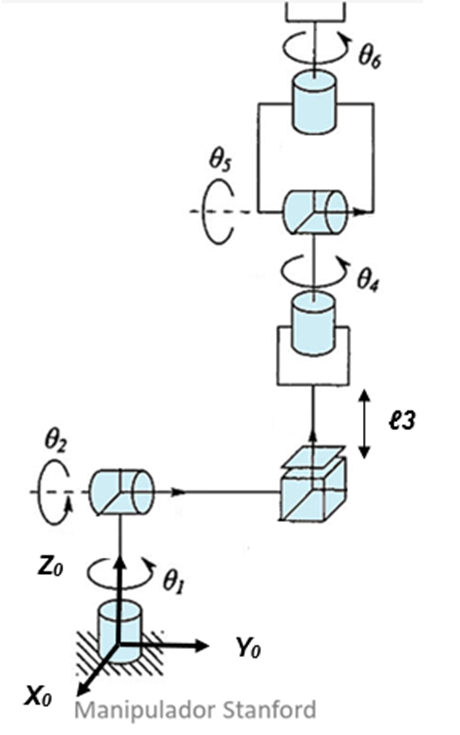

%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t) th2(t) l3(t) th4(t) th5(t) th6(t) t   %Angulos (y longitud l3) de cada articulación
syms th1p(t) th2p(t) l3p(t) th4p(t) th5p(t) th6p(t)   %Velocidades de cada articulación
syms th1pp(t) th2pp(t) l3pp(t) th4pp(t) th5pp(t) th6pp(t) %Aceleraciones de cada articulación
syms m1 m2 m3 m4 m5 m6 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 %Masas y matrices de Inercia
syms Ixx4 Iyy4 Izz4 Ixx5 Iyy5 Izz5 Ixx6 Iyy6 Izz6 %Masas y matrices de Inercia
syms l1 l2 l4 l5 l6 lc1 lc2 lc3 lc4 lc5 lc6 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

%Creamos el vector de coordenadas articulares
Q= [th1; th2; l3; th4; th5; th6];
%disp('Coordenadas generalizadas');
%pretty (Q);
 
%Creamos el vector de velocidades articulares
Qp= [th1p; th2p; l3p; th4p; th5p; th6p];
%disp('Velocidades generalizadas');
%pretty (Qp);
%Creamos el vector de aceleraciones articulares
Qpp= [th1pp; th2pp; l3pp; th4pp; th5pp; th6pp];
%disp('Aceleraciones generalizadas');
%pretty (Qpp);

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 1 0 0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Análisis de transformaciones

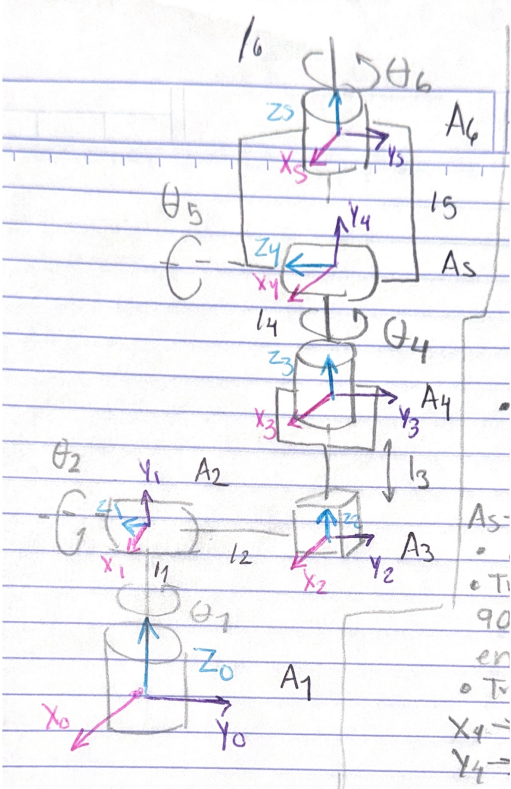

A1 → A2:

- Rotación en z0 de theta1(t).

- Rotación en x0 de 90°.

- Traslación en z0 de l1.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1)  0   sin(th1);
           sin(th1)  0  -cos(th1);
           0         1         0];

A2 → A3:

- Rotación en z1 de theta2(t).

- Rotación en x1 de -90°.

- Traslación en z1 de -l2.

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; 0; -l2];
%Matriz de rotación de la junta 2 respecto a 1
R(:,:,2)= [cos(th2)   0  -sin(th2);
           sin(th2)   0   cos(th2);
           0         -1         0];

A3 → A4:

- No hay rotación.

- Traslación en z2 de l3(t).

%Articulación 3
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0; l3];
%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= [1  0  0;
           0  1  0;
           0  0  1];

A4 → A5:

- Rotación en z3 de theta4(t).

- Rotación en x3 de 90°.

- Traslación en z3 de l4.

%Articulación 4 
%Posición de la articulación 4 respecto a 3
P(:,:,4)= [0; 0; l4];
%Matriz de rotación de la junta 4 respecto a 3 
R(:,:,4)= [0 -sin(th4)  cos(th4);
           0  cos(th4)  sin(th4);
          -1        0         0];

A5 → A6:

- Rotación en z4 de theta5(t).

- Rotación en x4 de -90°.

- Traslación en x4 de l5*cos(theta5(t)) y traslación en y4 de l5*sin(theta5(t)).

%Articulación 5
%Posición de la articulación 5 respecto a 4
P(:,:,5)= [l5*cos(th5); l5*sin(th5); 0];
%Matriz de rotación de la junta 5 respecto a 4
R(:,:,5)= [cos(th5)   0  -sin(th5);
           sin(th5)   0   cos(th5);
           0         -1         0];

A6:

- Rotación en z5 de theta6(t).

- No hay traslación.

%Articulación 6
%Posición de la articulación 6 respecto a 5
P(:,:,6)= [0; 0; 0];
%Matriz de rotación de la junta 6 respecto a 5
R(:,:,6)= [cos(th6) -sin(th6)  0;
           sin(th6)  cos(th6)  0;
           0         0         1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%CALCULAMOS LAS VELOCIDADES PARA CADA ESLABÓN%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 6  %%%%%%%%%%

%Calculamos el jacobiano lineal de forma analítica
Jv_a6(:,GDL)=PO(:,:,GDL);
Jw_a6(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a6(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a6(:,k)= RO(:,3,k-1);
        catch
            Jv_a6(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a6(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a6(:,k)= RO(:,3,k-1);
        catch
            Jv_a6(:,k)=[0,0,1];
        end
            Jw_a6(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a6= simplify (Jv_a6);
Jw_a6= simplify (Jw_a6);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac6= [Jv_a6;
      Jw_a6];
Jacobiano6= simplify(Jac6);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 6
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6


V6=simplify (Jv_a6*Qp);
pretty(V6)

/  l5 sin(th5(t)) th4p(t) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - th1p(t) (l2 cos(th1(t)) - l4 sin(th1(t)) sin(th2(t)) + l5 sin(th5(t)) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - sin(th1(t)) sin(th2(t)) l3(t) + l5 cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) #1 - cos(th1(t)) sin(th2(t)) l3p(t) - th5p(t) (l5 cos(th4(t)) cos(th5(t)) sin(th1(t)) + l5 cos(th1(t)) sin(th2(t)) sin(th5(t)) + l5 cos(th1(t)) cos(th2(t)) cos(th5(t)) sin(th4(t)))  \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             


disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 6');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 6


W6=simplify (Jw_a6*Qp);
pretty(W6)

/ sin(th1(t)) th2p(t) - th6p(t) (cos(th5(t)) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) + cos(th1(t)) sin(th2(t)) sin(th5(t))) - th5p(t) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - cos(th1(t)) sin(th2(t)) th4p(t) \
|                                                                                                                                                                                                                                                               |
| th5p(t) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + th6p(t) (cos(th5(t)) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - sin(th1(t)) sin(th2(t)) sin(th5(t))) - cos(th1(t)) th2p(t) - sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                                                                                                                 




%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 5  %%%%%%%%%%

%Calculamos el jacobiano lineal de forma analítica
Jv_a5(:,GDL-1)=PO(:,:,GDL-1);
Jw_a5(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a5(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a5(:,k)= RO(:,3,k-1);
        catch
            Jv_a5(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a5(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a5(:,k)= RO(:,3,k-1);
        catch
            Jv_a5(:,k)=[0,0,1];
        end
            Jw_a5(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a5= simplify (Jv_a5);
Jw_a5= simplify (Jw_a5);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac5= [Jv_a5;
      Jw_a5];
Jacobiano5 = simplify(Jac5);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 5
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 5');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 5


Qp=Qp(t);
V5=simplify (Jv_a5*Qp(1:5));
pretty(V5)

/  l5 sin(th5(t)) th4p(t) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - th1p(t) (l2 cos(th1(t)) - l4 sin(th1(t)) sin(th2(t)) + l5 sin(th5(t)) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - sin(th1(t)) sin(th2(t)) l3(t) + l5 cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) #1 - cos(th1(t)) sin(th2(t)) l3p(t) - th5p(t) (l5 cos(th4(t)) cos(th5(t)) sin(th1(t)) + l5 cos(th1(t)) sin(th2(t)) sin(th5(t)) + l5 cos(th1(t)) cos(th2(t)) cos(th5(t)) sin(th4(t)))  \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             


disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 5');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 5


W5=simplify (Jw_a5*Qp(1:5));
pretty(W5)

/ sin(th1(t)) th2p(t) - th5p(t) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - cos(th1(t)) sin(th2(t)) th4p(t) \
|                                                                                                                                 |
| th5p(t) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) - cos(th1(t)) th2p(t) - sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                 |
\                                 th1p(t) + cos(th2(t)) th4p(t) + cos(th4(t)) sin(th2(t)) th5p(t)                                 /





%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 4  %%%%%%%%%%

%Calculamos el jacobiano lineal de forma analítica
Jv_a4(:,GDL-2)=PO(:,:,GDL-2);
Jw_a4(:,GDL-2)=PO(:,:,GDL-2);

for k= 1:GDL-2
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a4(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a4(:,k)= RO(:,3,k-1);
        catch
            Jv_a4(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a4(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a4(:,k)= RO(:,3,k-1);
        catch
            Jv_a4(:,k)=[0,0,1];
        end
            Jw_a4(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a4= simplify (Jv_a4);
Jw_a4= simplify (Jw_a4);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac4= [Jv_a4;
      Jw_a4];
Jacobiano4= simplify(Jac4);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 4
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 4');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 4


V4=simplify (Jv_a4*Qp(1:4));
pretty(V4)

/  l5 sin(th5(t)) th4p(t) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - cos(th1(t)) th2p(t) #1 - cos(th1(t)) sin(th2(t)) l3p(t) - th1p(t) (l2 cos(th1(t)) - l4 sin(th1(t)) sin(th2(t)) + l5 sin(th5(t)) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - sin(th1(t)) sin(th2(t)) l3(t) + l5 cos(th5(t)) sin(th1(t)) sin(th2(t)))  \
|                                                                                                                                                                                                                                                                                                                                                                      |
| - th1p(t) (l2 sin(th1(t)) + l4 cos(th1(t)) sin(th2(t)) + l5 sin(th5(t)) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) + cos(th1(t)) sin(th2(t)) l3(t) - l5 cos(th1(t)) cos(th5(t)) sin(th2(t))) - sin(th1(t)) th2p(t) #1 - sin(th1(t)) sin(th2(t)) l3p(t) - l5 sin


disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 4');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 4


W4=simplify (Jw_a4*Qp(1:4));
pretty(W4)

/  sin(th1(t)) th2p(t) - cos(th1(t)) sin(th2(t)) th4p(t)  \
|                                                         |
| - cos(th1(t)) th2p(t) - sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                         |
\              th1p(t) + cos(th2(t)) th4p(t)              /





%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 3  %%%%%%%%%%

%Calculamos el jacobiano lineal de forma analítica
Jv_a3(:,GDL-3)=PO(:,:,GDL-3);
Jw_a3(:,GDL-3)=PO(:,:,GDL-3);

for k= 1:GDL-3
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a3(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a3(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)=[0,0,1];
        end
            Jw_a3(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a3= simplify (Jv_a3);
Jw_a3= simplify (Jw_a3);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac3= [Jv_a3;
      Jw_a3];
Jacobiano3= simplify(Jac3);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 3
 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3


V3=simplify (Jv_a3*Qp(1:3));
pretty(V3)

/ - th1p(t) (l2 cos(th1(t)) - l4 sin(th1(t)) sin(th2(t)) + l5 sin(th5(t)) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - sin(th1(t)) sin(th2(t)) l3(t) + l5 cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) #1 - cos(th1(t)) sin(th2(t)) l3p(t) \
|                                                                                                                                                                                                                                                                             |
| - th1p(t) (l2 sin(th1(t)) + l4 cos(th1(t)) sin(th2(t)) + l5 sin(th5(t)) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) + cos(th1(t)) sin(th2(t)) l3(t) - l5 cos(th1(t)) cos(th5(t)) sin(th2(t))) - sin(th1(t)) th2p(t) #1 - sin(th1(t)) sin(th2(t)) l3p(t) |
|                                                                                                                                                                                       


 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3


W3=simplify (Jw_a3*Qp(1:3));
pretty(W3)

/  sin(th1(t)) th2p(t) \
|                      |
| -cos(th1(t)) th2p(t) |
|                      |
\        th1p(t)       /





%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 2  %%%%%%%%%%

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a2(:,GDL-4)=PO(:,:,GDL-4);
Jw_a2(:,GDL-4)=PO(:,:,GDL-4);

for k= 1:GDL-4
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac2= [Jv_a2;
      Jw_a2];
Jacobiano2= simplify(Jac2);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 2
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2


V2=simplify (Jv_a2*Qp(1:2));  
pretty(V2)

/ - th1p(t) (l2 cos(th1(t)) - l4 sin(th1(t)) sin(th2(t)) + l5 sin(th5(t)) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - sin(th1(t)) sin(th2(t)) l3(t) + l5 cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) #1 \
|                                                                                                                                                                                                                                            |
| - th1p(t) (l2 sin(th1(t)) + l4 cos(th1(t)) sin(th2(t)) + l5 sin(th5(t)) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) + cos(th1(t)) sin(th2(t)) l3(t) - l5 cos(th1(t)) cos(th5(t)) sin(th2(t))) - sin(th1(t)) th2p(t) #1 |
|                                                                                                                                                                                                                                            |
\                                           

disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2


W2=simplify (Jw_a2*Qp(1:2));
pretty(W2)

/  sin(th1(t)) th2p(t) \
|                      |
| -cos(th1(t)) th2p(t) |
|                      |
\        th1p(t)       /






%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 1  %%%%%%%%%%%%%%%%%%%%%%%%%%

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL-5)=PO(:,:,GDL-5);
Jw_a1(:,GDL-5)=PO(:,:,GDL-5);

for k= 1:GDL-5
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-2)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-2));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 1
 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


V1=simplify (Jv_a1*Qp(1:1));
pretty(V1)

/  th1p(t) (l4 sin(th1(t)) sin(th2(t)) - l2 cos(th1(t)) + sin(th1(t)) sin(th2(t)) l3(t)) \
|                                                                                        |
| -th1p(t) (l2 sin(th1(t)) + l4 cos(th1(t)) sin(th2(t)) + cos(th1(t)) sin(th2(t)) l3(t)) |
|                                                                                        |
\                                            0                                           /



 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify (Jw_a1*Qp(1:1));
pretty(W1)

/    0    \
|         |
|    0    |
|         |
\ th1p(t) /





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
P01=subs(P(:,:,1)/2, l1, lc1);%La función subs sustituye l1 por lc1 en 
P12=subs(P(:,:,2)/2, l2, lc2); %la expresión P(:,:,1)/2
P23=subs(P(:,:,3)/2, l3, lc3);
P34=subs(P(:,:,4)/2, l4, lc4);
P45=subs(P(:,:,5)/2, l5, lc5);
P56=subs(P(:,:,6)/2, l6, lc6);

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

I3=[Ixx3 0 0; 
    0 Iyy3 0; 
    0 0 Izz3];

I4=[Ixx4 0 0; 
    0 Iyy4 0; 
    0 0 Izz4];

I5=[Ixx5 0 0; 
    0 Iyy5 0; 
    0 0 Izz5];

I6=[Ixx6 0 0; 
    0 Iyy6 0; 
    0 0 Izz6];

%Función de energía cinética

%Calculamos la energía cinética para cada uno de los eslabones%%%%%%%%%%

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

                                                                                              /        2                        2 \                                                                                       /                   2             2 \
             __                                                                               | #3 |l2|    #5 #4 #1   #4 #1 |l4|  |      __                                                                               | #5 #3 #1   #4 |l2|    #3 #1 |l4|  |
          #2 m1 (l2 sin(th1(t)) + l4 cos(th1(t)) sin(th2(t)) + cos(th1(t)) sin(th2(t)) l3(t)) | -------- + -------- + ----------- |   #2 m1 (l4 sin(th1(t)) sin(th2(t)) - l2 cos(th1(t)) + sin(th1(t)) sin(th2(t)) l3(t)) | -------- - -------- + ----------- |
Izz1 #2                                                                                       \    l2        l3(t)         l4     /                                                                                       \   l3(t)     



%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K2= simplify (K2);
pretty (K2);

                                                                                                                                                                                                                                                                                    /    /        2                       2                                  2                 2 \                           \                                                                                                                                                                                                                                                                             /    /        2                       2                                  2                 2 \                           \
                                                                                                                                                                                                                  


%Eslabón 3
V3_Total= V3+cross(W3,P23);
K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W3)'*(I3*W3);
disp('Energía Cinética en el Eslabón 3');

Energía Cinética en el Eslabón 3


K3= simplify (K3);
pretty (K3);

             /    /         2                         2                   2 \          \                                                                                                                                                                                                                                                                                                                                                                                                                                                        /    /        2                        2                                   2                  2 \                                       \                                                                                                                                                                                                                                                                                                              /    /        2                  


%Eslabón 4
V4_Total= V4+cross(W4,P34);
K4= (1/2*m4*(V4_Total))'*((V4_Total)) + (1/2*W4)'*(I4*W4);
disp('Energía Cinética en el Eslabón 4');

Energía Cinética en el Eslabón 4


K4= simplify (K4);
pretty (K4);

                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 / ___                                                                                                                                                                                      \                                                                                                           


%Eslabón 5
V5_Total= V5+cross(W5,P45);
K5= (1/2*m5*(V5_Total))'*((V5_Total)) + (1/2*W5)'*(I5*W5);
disp('Energía Cinética en el Eslabón 5');

Energía Cinética en el Eslabón 5


K5= simplify (K5);
pretty (K5);

   /                                                                               ___                        ___                                                                               \                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       


%Eslabón 6
V6_Total= V6+cross(W6,P56);
K6= (1/2*m6*(V6_Total))'*((V6_Total)) + (1/2*W6)'*(I6*W6);
disp('Energía Cinética en el Eslabón 6');

Energía Cinética en el Eslabón 6


K6= simplify (K6);
pretty (K6);

                                                                                    / _______   _______       _______       _______         \                                                                                                                                              / _______                           _______      _______       _______         \                                                                                                                                              / _______       _______       _______                          _______         \   __                                                                                                                                                                                                                                                                                                                                                                                              _______      __   _____     


K_Total= simplify (K1+K2+K3+K4+K5+K6);
disp('Energía Cinética Total');

Energía Cinética Total


pretty (K_Total);

                                                                                                                              /                 ___                         ___                               \                                                                                                                                                                                                          /                                       2 \                                                                                                                     /                                       2 \                                                                                                                                                                                                                                                                                                                                                                   / ___                            


%Energia Potencial  p=mgh

%Obtenemos las alturas respecto a la gravedad
h1= P01(3); %Tomo la altura paralela al eje z
h2= P12(2); %Tomo la altura paralela al eje y
h3= P23(3); %Tomo la altura paralela al eje z
h4= P34(3); %Tomo la altura paralela al eje z
h5= P45(2); %Tomo la altura paralela al eje y
h6= P56(3); %Tomo la altura paralela al eje z


U1=m1*g*h1

$$U1 = \frac{g\,{\mathrm{lc}}_{1}\,m_{1}}{2}$$

U2=m2*g*h2

$$U2 = 0$$

U3=m3*g*h3

$$U3 = \frac{g\,{\mathrm{lc}}_{3}\,m_{3}}{2}$$

U4=m4*g*h4

$$U4 = \frac{g\,{\mathrm{lc}}_{4}\,m_{4}}{2}$$

U5=m5*g*h5

$$U5 = \frac{g\,{\mathrm{lc}}_{5}\,m_{5}\,\sin\left({\mathrm{th}}_{5}\left(t\right)\right)}{2}$$

U6=m6*g*h6

$$U6 = 0$$


%Calculamos la energía potencial total
disp('Energía Potencial Total');

Energía Potencial Total


U_Total= U1 + U2 + U3 + U4 + U5 + U6;

%Obtenemos el Lagrangiano
disp('Lagrangiano');

Lagrangiano


Lagrangiano= simplify (K_Total-U_Total);
pretty (Lagrangiano);

                                                                                                                              /                 ___                         ___                               \                                                                                                                                                                                                          /                                       2 \                                                                                                                     /                                       2 \                                                                                                                                                                                                                                                                                                                                                                                                    


%Modelo de Energía
disp('Modelo de Energía');

Modelo de Energía


H= simplify (K_Total+U_Total);
pretty (H)

                                                                                                                              /                 ___                         ___                               \                                                                                                                                                                                                          /                                       2 \                                                                                                                     /                                       2 \                                                                                                                                                                                                                                                                                                                                                                                                    